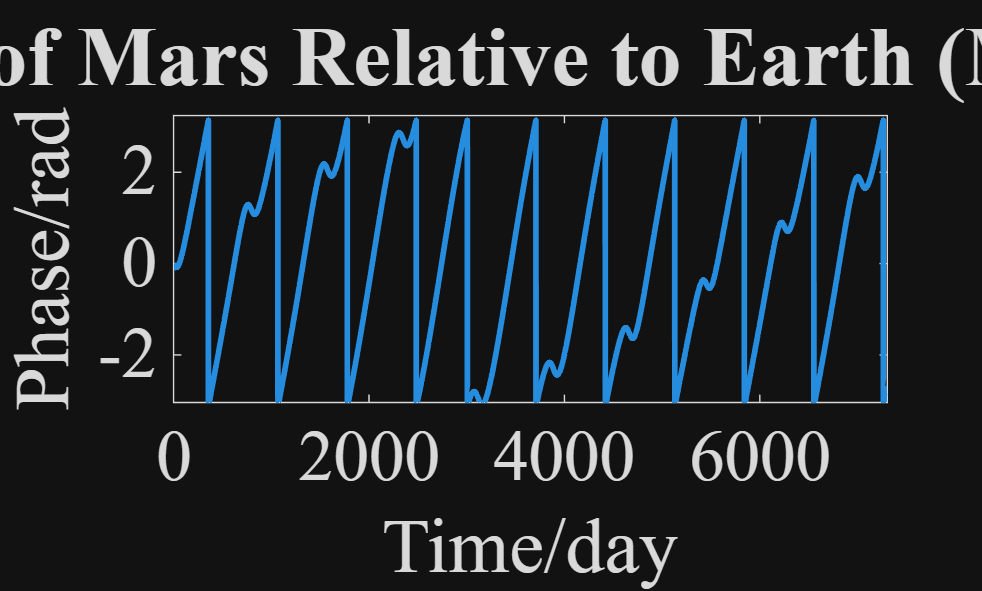

clear;
warning off
load calculated_data.mat

% Phase Plot
phase = atan2(y_rel, x_rel);
plot(t, phase, "-", "LineWidth", 2)
set(gca, "FontName", "Times New Roman", "FontSize", 25);
xlim([0, max(t)]);
ylim([-pi+0.1, pi+0.1]);
xlabel("Time/day");
ylabel("Phase/rad");
title("Phase Change of Mars Relative to Earth (Mordern Theory)", "FontSize", 30);
hold off

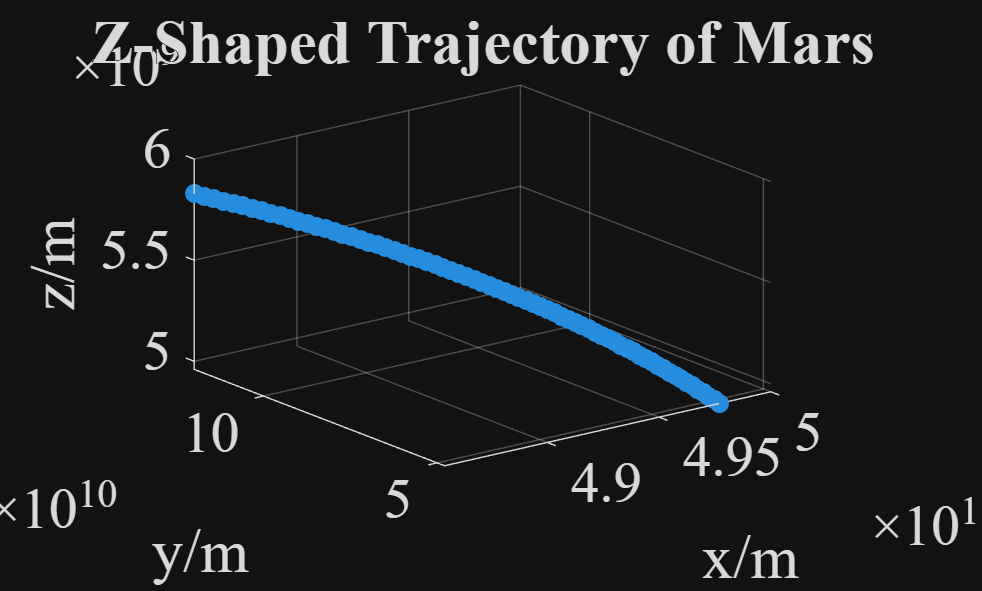


% Z-shaped plot
tspan_fix = [300, 370];

plot3(x_fix(tspan_fix(1):tspan_fix(2)), y_fix(tspan_fix(1):tspan_fix(2)), z_rel(tspan_fix(1):tspan_fix(2)), ".", "MarkerSize", 20)
set(gca, "FontSize", 20, "FontName", "Times New Roman");
xlabel("x/m");
ylabel("y/m");
zlabel("z/m");
grid on
title("Z-Shaped Trajectory of Mars");